# Лабораторная работа №1

Соболев А.М.

Веснин М.?.

Вариант: 25

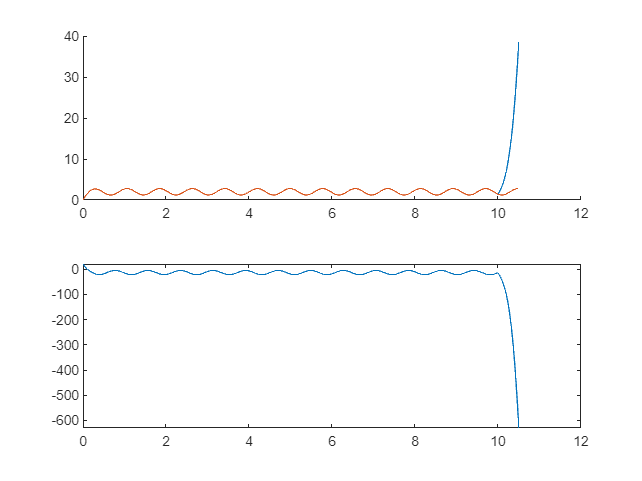

t = 10.5; % Время симуляции
lambda = 10;
theta = 7;

n_adapt = sim("Lab1_nonadaptive.slx");


% Графики
figure
subplot(2,1,1)
hold on
plot(n_adapt.simout.time, n_adapt.simout.signals.values(:,2));
plot(n_adapt.simout.time, n_adapt.simout.signals.values(:,3));
hold off
subplot(2,1,2)
plot(n_adapt.simout.time, n_adapt.simout.signals.values(:,1));

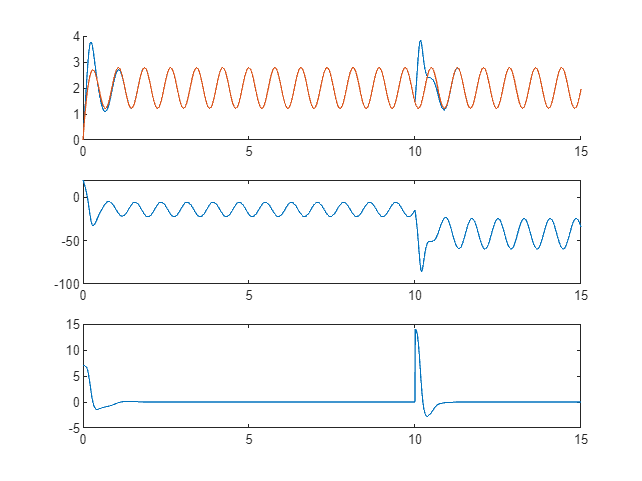

t = 15; % Время симуляции
gamma = 10;

adapt = sim("Lab1_adaptive.slx");
% Графики
figure
subplot(3,1,1)
hold on
plot(adapt.simout.time, adapt.simout.signals.values(:,2)); % x
plot(adapt.simout.time, adapt.simout.signals.values(:,3)); % dx
hold off
subplot(3,1,2)
plot(adapt.simout.time, adapt.simout.signals.values(:,1)); % u
subplot(3,1,3)
plot(adapt.simout.time, adapt.simout.signals.values(:,4)); % theta-theta_hat

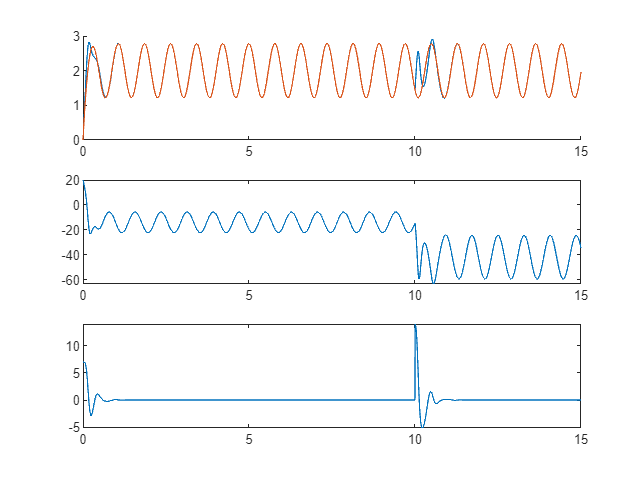

gamma = 50;

adapt2 = sim("Lab1_adaptive.slx");
% Графики
figure
subplot(3,1,1)
hold on
plot(adapt2.simout.time, adapt2.simout.signals.values(:,2)); % x
plot(adapt2.simout.time, adapt2.simout.signals.values(:,3)); % dx
hold off
subplot(3,1,2)
plot(adapt2.simout.time, adapt2.simout.signals.values(:,1)); % u
subplot(3,1,3)
plot(adapt2.simout.time, adapt2.simout.signals.values(:,4)); % theta-theta_hat